# Notebook 7: Probability of False Detection

This will be a notebook that is used for the creation of the control experiments for the Monte Carlo simulations. This is going to be testing of the KCC for the probability of false detection exploration. We want the pure noise signals to reveal no peaks for correlation outputs. This will be traced for multiple different SNR values from 1 to -30. This is going to be a primary focus in the results section.

Each SNR value will have 5-10 trials of the correlation value for the signals. They will be repeated and then recorded.

## Developing signals

% --Setup
    clear; clc; format compact; close all; 
    % cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Pure white noise data
    data = randi(100, 1, length(ref_signal))./6.435;
    data = data - mean(data);
    time = 0:1/fs:T - (1/fs);

% --Calculate noise power
    noise_power = sum(data.^2)/(2*length(data) + 1);
    SNR = 10*log10(noise_power);
    fprintf("Noise power of the dataset is %3.3f dB",SNR)

Noise power of the dataset is 10.003 dB

## Detection Simulations

For these simulations, we should only get out random noise content, meaning that there is NO correlation, this can be either a random set of data, or a very low correlation with a high first value indicating a very high variance within the signal, meaning no correlated data.

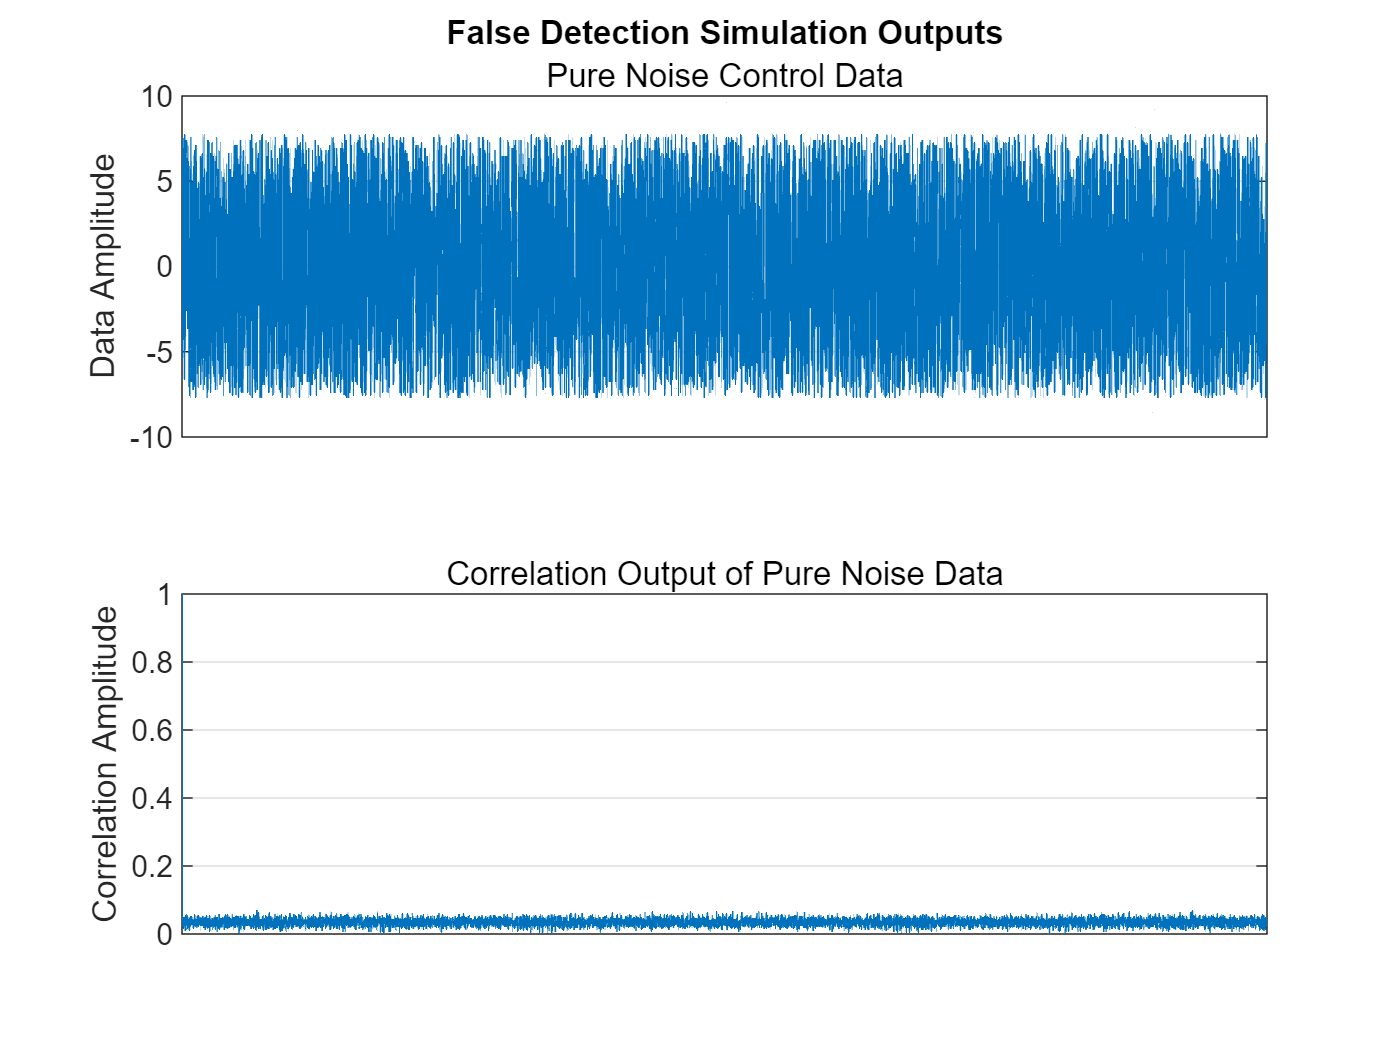

% --Call correlation
    corr_output = kxcorr(data, ref_signal);

% --Plot outputs
    figure()
    subplot(2,1,1)
    plot(data)
        ylabel('Data Amplitude')
        subtitle("Pure Noise Control Data")
        hold on
        grid on
        xlim([0 length(data)])
        title("False Detection Simulation Outputs")
        set(gca,'XTick',[])

    subplot(2,1,2)
    plot(corr_output)
        ylabel('Correlation Amplitude')
        hold on
        grid on 
        subtitle("Correlation Output of Pure Noise Data")
        xlim([0 length(data)])
        set(gca,'XTick',[])

% --Calculating correlation coefficient
    correlation_coeff = mean(corr_output(2:end));
    fprintf("Correlation coefficient is %3.3f \n", correlation_coeff)

Correlation coefficient is 0.035 


## Results Recording

This section is going to be the correlation of the noise recordings, a 0 means no correlation, 1 means a correlation is present in the simulation.

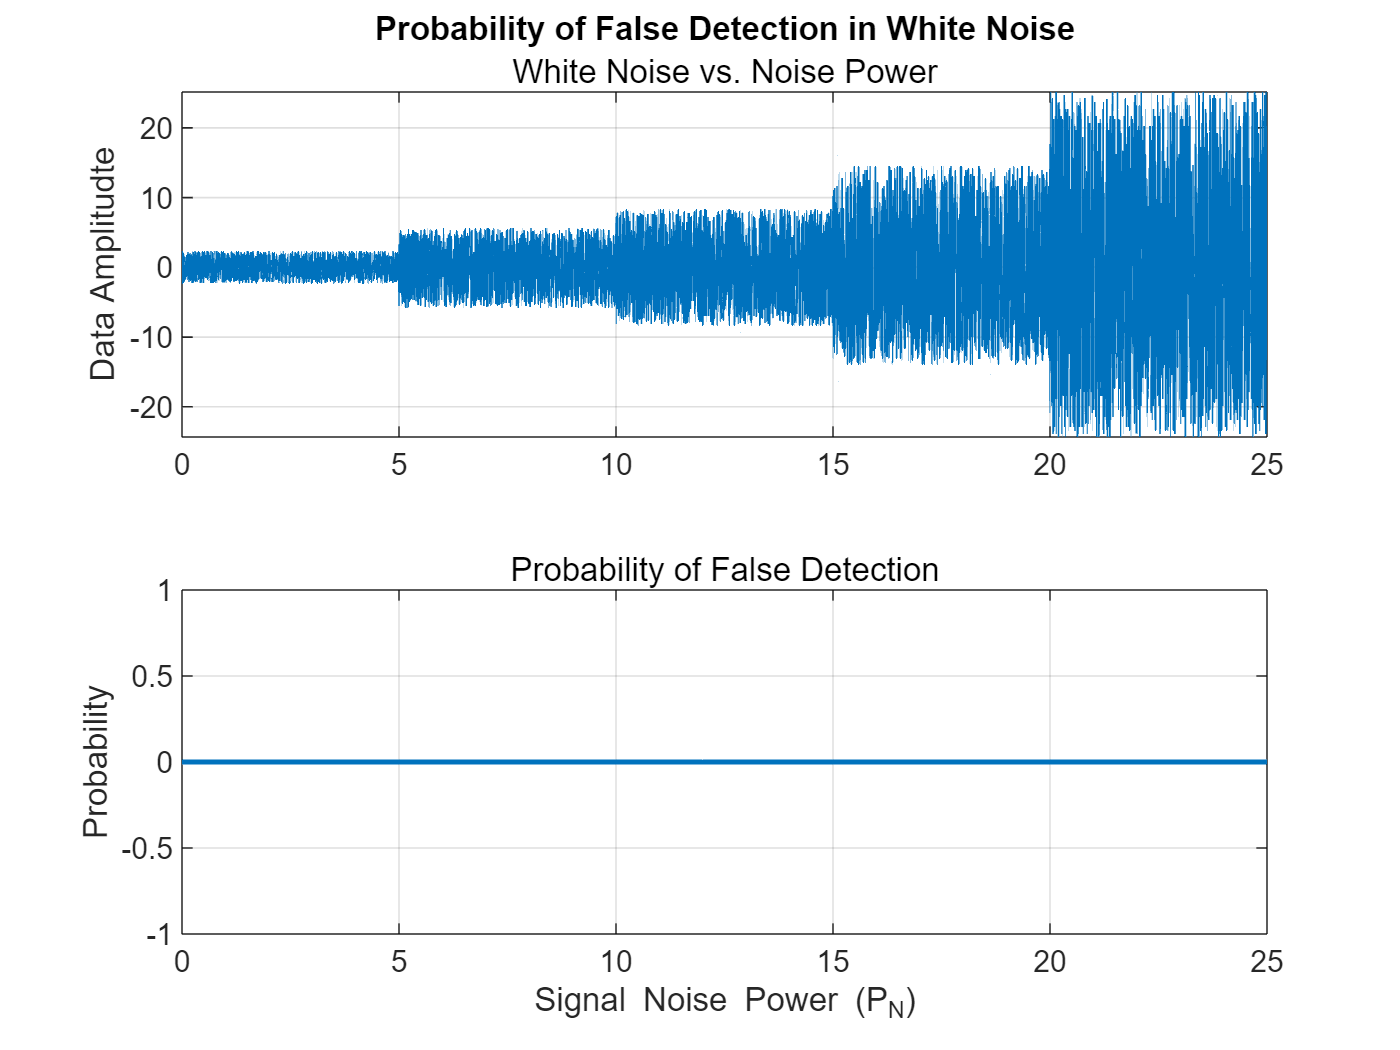

% --Simulation Results for 0dB noise power
    power_0dB_results = [0, 0, 0, 0, 0];
    lengths_0dB = zeros(1,length(power_0dB_results));

% --Simulation Results for 5dB noise power
    power_5dB_results = [0, 0, 0, 0, 0];
    lengths_5dB = 5 .* ones(1, length(power_5dB_results));

% --Simulation results for 10dB noise power
    power_10dB_results = [0, 0, 0, 0, 0];
    lengths_10dB = 10 .* ones(1, length(power_10dB_results));

% --Simulation results for 12dB noise power
    power_12dB_results = [0, 0, 0, 0, 0, 0];
    lengths_12dB = 12 .* ones(1, length(power_12dB_results));

% --Simulation results for 15dB noise power
    power_15dB_results = [0, 0, 0, 0, 0];
    lengths_15dB = 15 .* ones(1, length(power_15dB_results));

% --Simulation results for 20dB noise power
    power_20dB_results = [0, 0, 0];
    lengths_20dB = 20 .* ones(1, length(power_20dB_results));

% --Simulation results for 25dB noise power
    power_25dB_results = [0, 0, 0, 0];
    lengths_25dB = 25 .* ones(1, length(power_25dB_results));

% --Combining together to make graphs
    results = [power_0dB_results, power_5dB_results, power_10dB_results, power_12dB_results, power_15dB_results, power_20dB_results, power_25dB_results];
    lengths = [lengths_0dB, lengths_5dB, lengths_10dB, lengths_12dB, lengths_15dB, lengths_20dB, lengths_25dB];

% --Load in dataset
    cd("\")
    cd("C:\Users\Sam Kramer\Desktop")
    load("random_noie.mat");
        x = linspace(0, 25, 10001);

% --Creating graphic
    figure()
    subplot(2,1,1)
    plot(x, asdf)
        xlim([0 25])
        grid on
        ylabel("Data Amplitudte")
        subtitle("White Noise vs. Noise Power")
        title("Probability of False Detection in White Noise")

    subplot(2,1,2)
    plot(lengths, results, "LineWidth", 1.5)
        hold on
        grid on
        subtitle("Probability of False Detection")
        ylabel("Probability")
        xlabel("Signal Noise Power (P_N)")

## Noise Identification

This section is to identify what kind of noise is being created with our data, i.e. white noise, or colored noise.

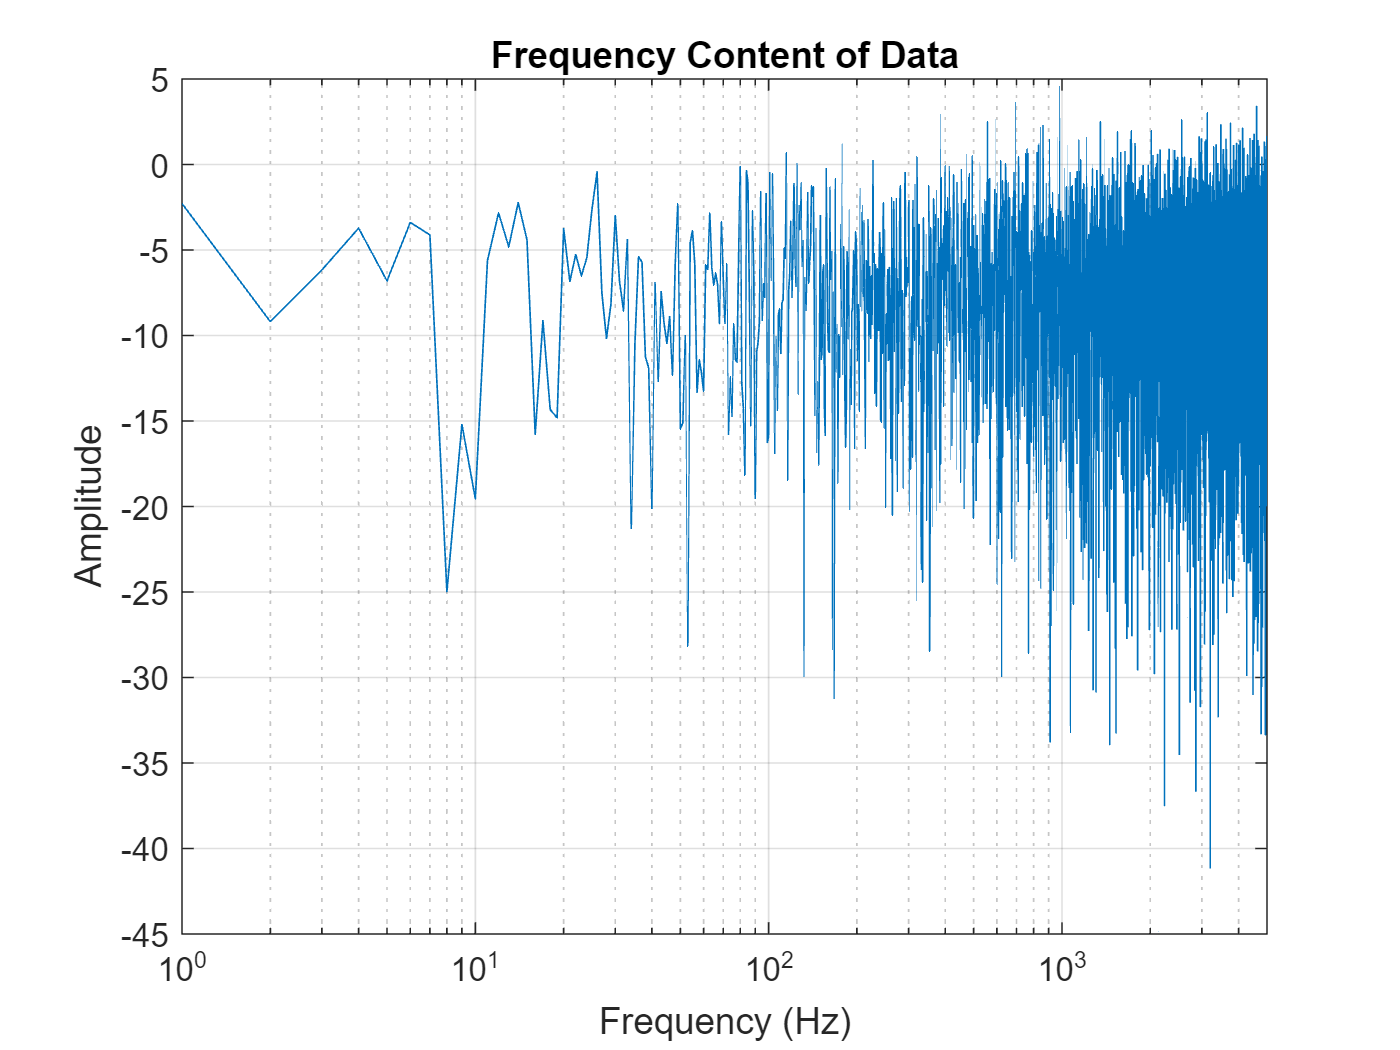

% --Taking FFT of signals
    f_data = fft(data);
    f_data_mag = abs(f_data);
    f_data_amp = 2 .* f_data_mag ./ (length(data));
    f_data_amp = f_data_amp(1:round(length(f_data_amp) / 2));
    f_data_amp = mag2db(f_data_amp);

    frequencies = (1/T).*(0:length(f_data_amp) - 1);

% --Plotting Noise
    figure()
    semilogx(frequencies, f_data_amp);
    hold on
    grid on
    xlabel('Frequency (Hz)')
    ylabel('Amplitude')
    xlim([0 5000])
    title('Frequency Content of Data')

This would be considered white noise because the slope is 0 and the mean remains the same across the entire spectrum on a logarithmic spectrum. 

## Function Definitions

### Linear Absolute Value

                
$$K(x,y) = |(x + y)|$$


function kf = Labs_kernel(x, y) % Time domain defintion of kernel

    % --Find the kernel
        kf = abs(x + y);

end

### Cubic Kernel

                
$$K(x,y) = -(x \odot y + 1)^3$$


function kf = cubic_kernel(x, y)

    % --Find kernel
        kf = (x.*y + 1).^3;

end

### RBF Kernel

                
$$K(x,y) = exp(\frac{-(x^2 + y^2)}{2\sigma})$$


function kf = rbf_kernel(x, y)
        
    % --Parameters
        sigma = 0.3;

    % --Find kernel
        kf = exp(-1.*(x.^2 + y.^2) ./ (2*sigma));

end

### KXCorr function

function corr = kxcorr(x, y)

    % --Take Kernels of the signals
        kx = Labs_kernel(x,x);
        kx_hat = fft(kx);

        ky = Labs_kernel(x,y);
        ky_hat = fft(ky);

    % --Create correlation output
        corr_hat = kx_hat .* conj(ones(1, length(ky_hat)) .* ky_hat);
        corr = ifft(corr_hat);
        corr = corr - min(corr);
        corr = corr ./ max(corr);

end